% 1 - Bone W:2000 L:500
% 2 - Lung W:1600 L:-600
% 3 - Abdomen W:400 L:50
% 4 - Brain W:700 L:30
% 5 - Soft tissue W:350 L:50
% 6- Liver W:160 L:50

windows = [
    [2000 500]; 
    [1600 -600];
    [400 50];
    [700 30];
    [350 50];
    [160 50];
   ];


% s = size(vol);
% slice = vol(:,:,50);
% imshow(slice);

fixed = readMedicalVolume("1\");
moving = readMedicalVolume("2\");

wl = 50

wl = 50

ww = 400

ww = 400


v1 = applyWindowLevel(fixed.vol,ww,wl);

v2 = applyWindowLevel(moving.vol,ww,wl);


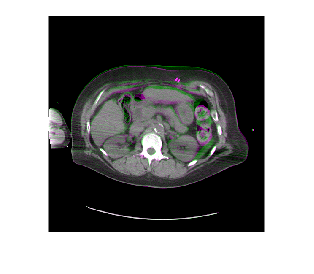

c1 = v1(:,:,50);
c2 = v2(:,:,50);
f = imfuse(c1,c2,'falsecolor');
imshow(f)